# MATLAB Exercise 3.6:

This live script is for use with the textbook

*Continuous-Time Signals and Systems: A MATLAB Integrated Approach*

by Oktay Alkin, CRC Press, 2025.

Approximate the TFS coefficients of a periodic signal using the function  `ss_tfsapprox()`.

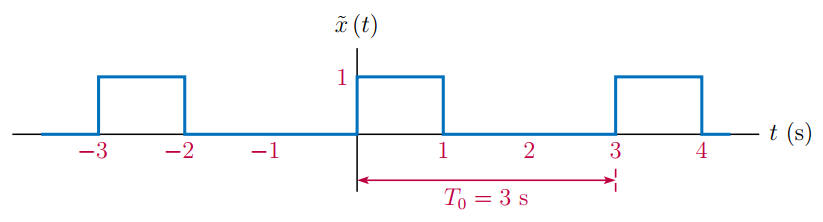

Pay special attention to how sampling time instants are obtained: The first sample is at $t=0$, and the last one is at $t=\frac{3\,(N-1)}{N}$, not quite at $t=3$ s.

N = 1000; % Number of samples per period
M = 10; % Number of harmonics
%
T0 = 3;            % Fundamental period
t = [0:N-1]/N*T0;  % Vector of time instants for one period
x = @(t) (t<=1);   % Anonymous function for one period of the signal
xVect = x(t);      % One period of the signal as a vector
[a0,a,b] = ss_tfsapprox(xVect,M); % Compute approximate TFS coefficients

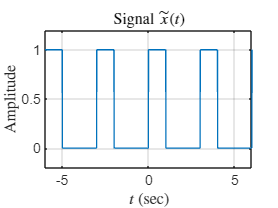

% Compute finite-harmonic approximation
t = [-6:0.01:6];   % Vector of time instants
xTilde = x(mod(t,T0));  % Create the periodic signal of Example 4.1
plot(t,xTilde); grid;
axis([-6,6,-0.2,1.2]);
set(0,'defaultTextInterpreter','latex');
xlabel('$t$ (sec)');
ylabel('Amplitude');
title('Signal $\tilde{x}(t)$');

% Display TFS coefficients as a table
Tbl = table([0:M]',[a0;a],[NaN;b],'VariableNames',["k","a","b"]);
head(Tbl,M+1);

    k         a             b     
    __    _________    ___________

     0        0.334            NaN
     1       0.2765        0.47775
     2       -0.137        0.23844
     3    0.0013333    -4.1888e-06
     4     0.069751        0.11965
     5    -0.054301         0.0952
     6    0.0013334    -8.3778e-06
     7     0.040216       0.068492
     8    -0.033627       0.059387
     9    0.0013334    -1.2567e-05
    10     0.028403       0.048026



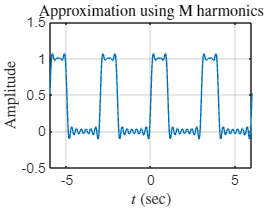

% Compute and graph finite-harmonic approximation
xHat = a0*ones(size(t));  % Vector for finite-harmonic approximation
omega0 = 2*pi/T0;  % Fundamental frequency in rad/s
for i = 1:M
  xHat = xHat+a(i)*cos(i*omega0*t)+b(i)*sin(i*omega0*t);  % Eqn. (3.47)  
end
plot(t,real(xHat)); grid;
axis([-6,6,-0.5,1.5]);
title('Approximation using M harmonics'); 
xlabel('$t$ (sec)');
ylabel('Amplitude');

set(0,'defaultTextInterpreter','tex');